# Singulärwertzerlegung

Wir betrachten die Matrix 

     $A=A_1=\pmatrix{1&-1 \cr 1/4&-1 \cr -1&1}$      oder  $A=A_2=\pmatrix{1&-1 \cr 0&-1 \cr -1&2}$

 und die zugehörige Singulärwertzerlegung $A=U \Sigma V^T$,  $V \in \mathbb{R}^{2 \times 2}$, $U \in \mathbb{R}^{3 \times 3}$.

# Aktivität:

Wählen Sie das Beispiel 1 oder  2 und ein $x \in \mathbb R^2$, mit $\|x\|_\infty \leq 2$. Beispiele: $x=(1, 1.4)^T$, $x=(-1,0)^T$, 

bsp =2;
A=example_A(1)

A =     1.0000   -1.0000
    0.2500   -1.0000
   -1.0000    1.0000


x= [0.5; 1.5]

x =     0.5000
    1.5000


[U,S,V]= svd(A)

U =    -0.6401    0.3004    0.7071
   -0.4248   -0.9053   -0.0000
    0.6401   -0.3004    0.7071


S =     2.1976         0
         0    0.4826
         0         0


V =    -0.6309    0.7759
    0.7759    0.6309


Es werden nacheinander 

     $r=V^Tx=(x^Tv_1)v_1 +(x^Tv_2)v_2 ,
$    (Zerlegung von $x$ in der $V$-Basis in $\mathbb{R}^2$)

     $s= \Sigma r,$    (Stauchung/Streckung entlang der Koordinatenachsen)

     $\sum_{i=1}^2 s_i u_i=Us= U\Sigma V^Tx = Ax
$    (Darstellung $Ax$ in der $U$-Basis in $\mathbb R^3$)

berechnet und visualisiert.

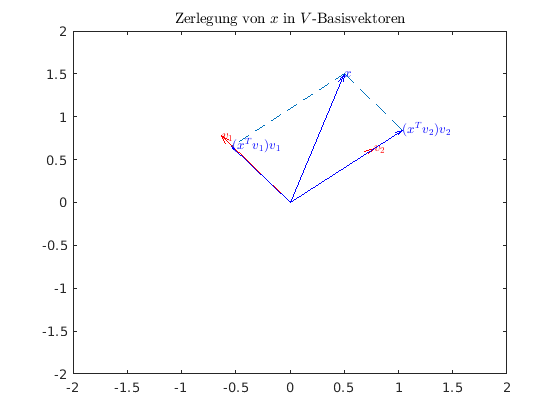

r=ZerlegungV(V,x);

fprintf('\n Vektor V^T*x: \n');


 Vektor V^T*x: 


r

r =     0.8484
    1.3343


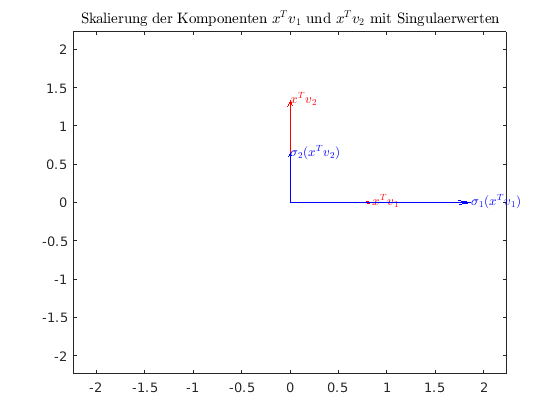

s=Skalierung(S,r);

fprintf('\n Vektor s: \n');


 Vektor s: 


s

s =     1.8644
    0.6440
         0


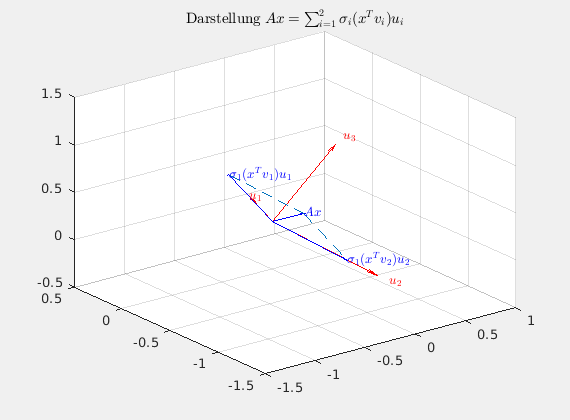

y=ZerlegungU(U,s);

fprintf('\n Vektor U*s=Ax: \n');


 Vektor U*s=Ax: 


y

y =    -1.0000
   -1.3750
    1.0000


# Aktivität:

Schauen Sie sich die geomettrischen Darstellungen der einzelnen Schritte genau an.

function A=example_A(i)
    if i==1
        A= [1 -1; 0.25 -1; -1 1];
    end;
    if i==2
       A= [1 -1; 0 -1; -1 2];
    end
end

function Vx=ZerlegungV(V,x)
o= [0 0];
quiver(o(1:2),o(1:2), V(1,:),V(2,:),0,"Color","red");
    text( V(1,:),V(2,:), {'$v_1$';'$v_2$'}, "Interpreter","latex","Color","red");
  axis([-2 2 -2 2]);  
  hold on;
  quiver(0,0,x(1),x(2),0,"Color","blue");
  text(x(1),x(2),{'$x$'}, "Interpreter","latex","Color","blue");
  vt1=(x'*V(:,1))*V(:,1);
  quiver(0,0,vt1(1),vt1(2),0,"Color","blue");
  text(vt1(1),vt1(2),{'$(x^Tv_1)v_1$'}, "Interpreter","latex","Color","blue");
  line([x(1);vt1(1)], [x(2);vt1(2)],'LineStyle','--');
  vt2=(x'*V(:,2))*V(:,2);
  quiver(0,0,vt2(1),vt2(2),0,"Color","blue");
  text(vt2(1),vt2(2),{'$(x^Tv_2)v_2$'}, "Interpreter","latex","Color","blue");
  line([x(1);vt2(1)], [x(2);vt2(2)],'LineStyle','--');
  title('Zerlegung von $x$ in $V$-Basisvektoren','Interpreter','latex');
  Vx=V*x;
  hold off;
end
    

function Sr=Skalierung(S,r)
  Sr=S*r;
  quiver(0,0,r(1),0,0,"Color","red");
  text(r(1),0,{'$x^Tv_1$'}, "Interpreter","latex","Color","red");
  hold on;
  s1=1.2*norm([Sr;r],'inf'); 
  axis([-s1 s1 -s1 s1]); 
  quiver(0,0,0,r(2),0,"Color","red");
  text(0,r(2),{'$x^Tv_2$'}, "Interpreter","latex","Color","red");
  quiver(0,0,Sr(1),0,0,"Color","blue");
  text(Sr(1),0,{'$\sigma_1(x^Tv_1)$'}, "Interpreter","latex","Color","blue");
  quiver(0,0,0,Sr(2),0,"Color","blue");
  text(0,Sr(2),{'$\sigma_2(x^Tv_2)$'}, "Interpreter","latex","Color","blue");
  title('Skalierung der Komponenten $x^Tv_1$ und $x^Tv_2$ mit Singulaerwerten','Interpreter','latex');
  hold off;
end
    

function y=ZerlegungU(U,s)
     figure(3);
      rotate3d on;
      axis equal;
      o= [0 0 0];
      quiver3(o,o,o, U(1,:),U(2,:),U(3,:), "Color","red");
    text( U(1,:),U(2,:),U(3,:),  {'$u_1$';'$u_2$';'$u_3$'}, "Interpreter","latex",...
        "Color","red");
    hold on;
    y1=s(1)*U(:,1); y2=s(2)*U(:,2);
     quiver3(0,0,0,y1(1),y1(2),y1(3),0,"Color","blue");
     text(y1(1),y1(2),y1(3),{'$\sigma_1(x^Tv_1)u_1$'}, "Interpreter","latex","Color","blue");
     quiver3(0,0,0,y2(1),y2(2),y2(3),0,"Color","blue");
     text(y2(1),y2(2),y2(3),{'$\sigma_1(x^Tv_2)u_2$'}, "Interpreter","latex","Color","blue");
   y=U*s;
    quiver3(0,0,0,y(1),y(2),y(3),0,"Color","blue");
     text(y(1),y(2),y(3),{'$Ax$'}, "Interpreter","latex","Color","blue");
     line([y(1);y1(1)], [y(2);y1(2)],[y(3);y1(3)],'LineStyle','--');
      line([y(1);y2(1)], [y(2);y2(2)],[y(3);y2(3)],'LineStyle','--');
      title('Darstellung $Ax=\sum_{i=1}^2 \sigma_i (x^T v_i) u_i$','Interpreter','latex');
   hold off;
end